## Radiator requirements and operating conditions

The radiator is used to cool the cooling liquid after leaving the cold plate back to its desired cooling temperature. The air is assumed to have ambient room temperature of a maximum of 20°C. A fan is used to create the airflow. The coolant inlet temperature is entering the radiator at 30°C, which is the maximum cold plate outlet temperature and should be cooled down to 25°C. 

#### Operating conditions

QDiss           = simscape.Value(2000, "W") + simscape.Value(10, "W");  % Heat to be dissipated by radiator
deltaTCoolant   = simscape.Value(5, "deltadegC");                       % Maximum temperature rise
TCoolantIn      = simscape.Value(25, "degC");                           % Assumed coolant inlet temperature
TCoolantOutMax  = simscape.Value(30, "degC");                           % Maximum coolant outlet temperature = Raditor inlet temperature
TAmbient        = simscape.Value(20, "degC");                           % Ambient temperature
pLoop           = simscape.Value(2, "bar");                             % Pressure in coolant loop
VDotAir         = simscape.Value(0.8, "m^3/s");                         % Assumed air flow rate from fan
pAmbient        = simscape.Value(1, "atm");                             % Ambient pressure

#### Water properties at 25°C

cpCoolant       = simscape.Value(4180.74, "J/(kg*K)");      % Coolant heat cpacity
rhoCoolant      = simscape.Value(997.137, "kg/m^3");        % Coolant density
muCoolant       = simscape.Value(8.89995e-4, "Pa*s");       % Coolant dynamic Pa·s
kCoolant        = simscape.Value(0.607, "W/(m*K)");         % Coolant thermal conductivity 
PrCoolant       = simscape.Value(6.134, "1");               % Coolant Prandtl number

#### Air properties at 20°C and ambient pressure

cpAir           = simscape.Value(1006, "J/(kg*K)");         % Air heat cpacity
rhoAir          = simscape.Value(1.204, "kg/m^3");          % Air density
kinViscAir      = simscape.Value(15e-6, "m^2/s");           % Air kinematic viscosity
PrAir           = simscape.Value(0.71, "1");                % Air Prandtl number
kAir            = simscape.Value(0.026, "W/(m*K)");         % Air thermal conductivity 

#### Coolant flow rate

The flow rate used in the calculations is the nominal flow rate as determined in [ColdPlate](matlab:open('.\ColdPlate.mlx')).

mDot    = QDiss/(cpCoolant*deltaTCoolant); % Coolant mass flow rate
VDot    = mDot/rhoCoolant;                 % Coolant volumetric flow rate

#### Sizing the radiator 

We will use the assumed air flow rate to roughly estimate the required radiator surface area on the air size. The total heat to be transfered is the same as the heat load of 2000 W. The average temperature driving force will be assume

mDotAir    = VDotAir*rhoAir;                                        % Air mass flow rate 
TAirOut    = QDiss/mDotAir/cpAir+convert(TAmbient,"K","affine")     % Air radiator outlet temperature

TAirOut =   295.2243 (K)



dT1 = convert(TCoolantIn - TAmbient, "deltaK","linear");                
dT2 = convert(convert(TCoolantOutMax, "K", "affine") - TAirOut,"deltaK","linear");

dTlm = (dT1-dT2)/log(dT1/dT2);                                      % Logarithmic temperature difference for steady state

htcAir = simscape.Value(120,"W/(m^2*K)");                           % Assumed heat transfer coefficient
A = QDiss/htcAir/dTlm;                                              % Required area
disp(A)

    2.6374 (K*m^2/deltaK)



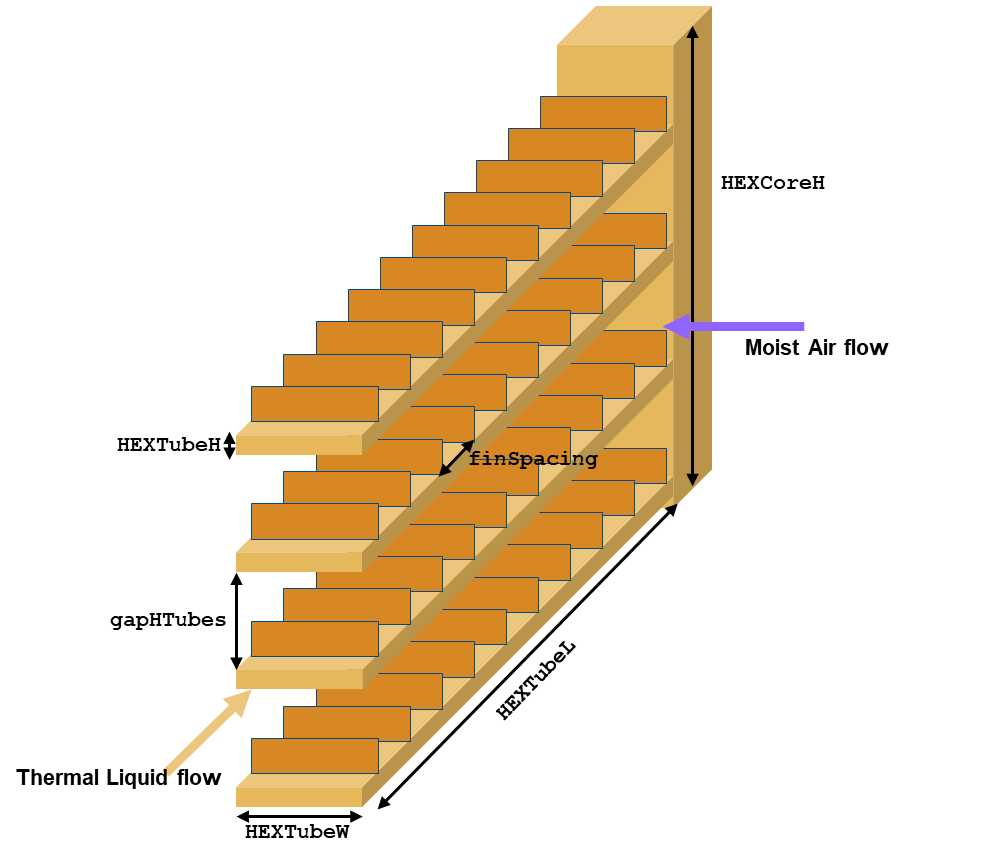

We will use the component [Heat Exchanger (TL-MA)](https://www.mathworks.com/help/releases/R2025a/hydro/ref/heatexchangertlma.html), which allows us to model a *Flow inside one or more tubes* on the Thermal Liquid (the coolant) side. We can use the *Generic *model on the Moist Air (the ambient air) side. For the setup we calculate some derived geometric parameters needed. Additional derived parameters include wall thermal resistance and wall thermal mass. 

HEXCoreL        = simscape.Value(350, "mm");        
HEXCoreH        = simscape.Value(350, "mm");       
HEXCoreW        = simscape.Value(88, "mm");         
HEXTubeW        = simscape.Value(88, "mm");         
HEXTubeH        = simscape.Value(3, "mm");          
HEXTubeL        = simscape.Value(350, "mm");
HEXTubeD        = simscape.Value(1, "mm");
numTubes        = 16;
tubeRoughness   = simscape.Value(15e-6, "m");
finEfficiency   = 0.75;                        
finSpacing      = simscape.Value(2, "mm");
tubeK           = simscape.Value(167, "W/(m*K)");
tubeRho         = simscape.Value(2700, "kg/m^3");
tubeCp          = simscape.Value(880, "J/(kg*K)");


HEXTubeWOuter = HEXTubeW+2*HEXTubeD;                                        % Heat exchanger tube outer width
HEXTubeHOuter = HEXTubeH+2*HEXTubeD;                                        % Heat exchanger tube outer height

tubesCrossArea = HEXTubeW*HEXTubeH;                                         % Heat exchanger tube cross-sectional area

areaOuterTubes = numTubes*2*(HEXTubeWOuter+HEXTubeHOuter)*HEXTubeL;         % Surface area of all tubes
areaInnerTubes = numTubes*2*(HEXTubeW+HEXTubeH)*HEXTubeL;                   % Inner area of tubes for heat transfer

tubesDh= 2*HEXTubeW*HEXTubeH/(HEXTubeW+HEXTubeH);                           % Hydraulic diameter tubes

gapHTubes = (HEXCoreH - numTubes*HEXTubeH)/(numTubes - 1);                  % Gap between tubes
areaAirFlow = (numTubes - 1)*HEXTubeL*gapHTubes;                            % Flow area on air side
airDh = 4*areaAirFlow/((numTubes-1)*2*(HEXTubeL+gapHTubes));                % Hydraulic diameter air side
numFins = (numTubes-1)*HEXCoreH/finSpacing;                                 % Number of fins

areaAirFins = 2*numFins*HEXCoreW*gapHTubes;                                 % Surface area of fins

areaResistance = numTubes*areaOuterTubes;                                   % Surface area of tubes used to calculat wall thermal resistance
HEXThermalResistance = HEXTubeD/tubeK/areaResistance;                       % Tube wall thermal resistance                                 
volumeTubes = (HEXTubeWOuter*HEXTubeHOuter-HEXTubeW*HEXTubeH)*HEXTubeL;     % Volume per tube
HEXWallMass = numTubes*tubeRho*volumeTubes;                                 % Combined tube mass


For the Moist Air side in the heat exchanger block, the flow geometry will be set to *Generic *in this case the model uses the Colburn equation to calculate the Nusselt number. The select coefficients, we calculate the Reynolds number at nominal operating conditions. On the air side we will add a Flow Resistance MA to account for a small additional pressure loss associated with the air intake. 

Re = VDotAir*airDh/(kinViscAir*areaAirFlow);                                % Reynolds on air side at nominal conditions
HEXColburnCoefficients = [0.211, .651, .273];                               % Literature Colburn equation coefficients for Reynolds number at nominal operating conditions

dpNominalAir = simscape.Value(5e-4, "MPa");  

We will test this in a Simscape model. 

open_system("example_Radiator")

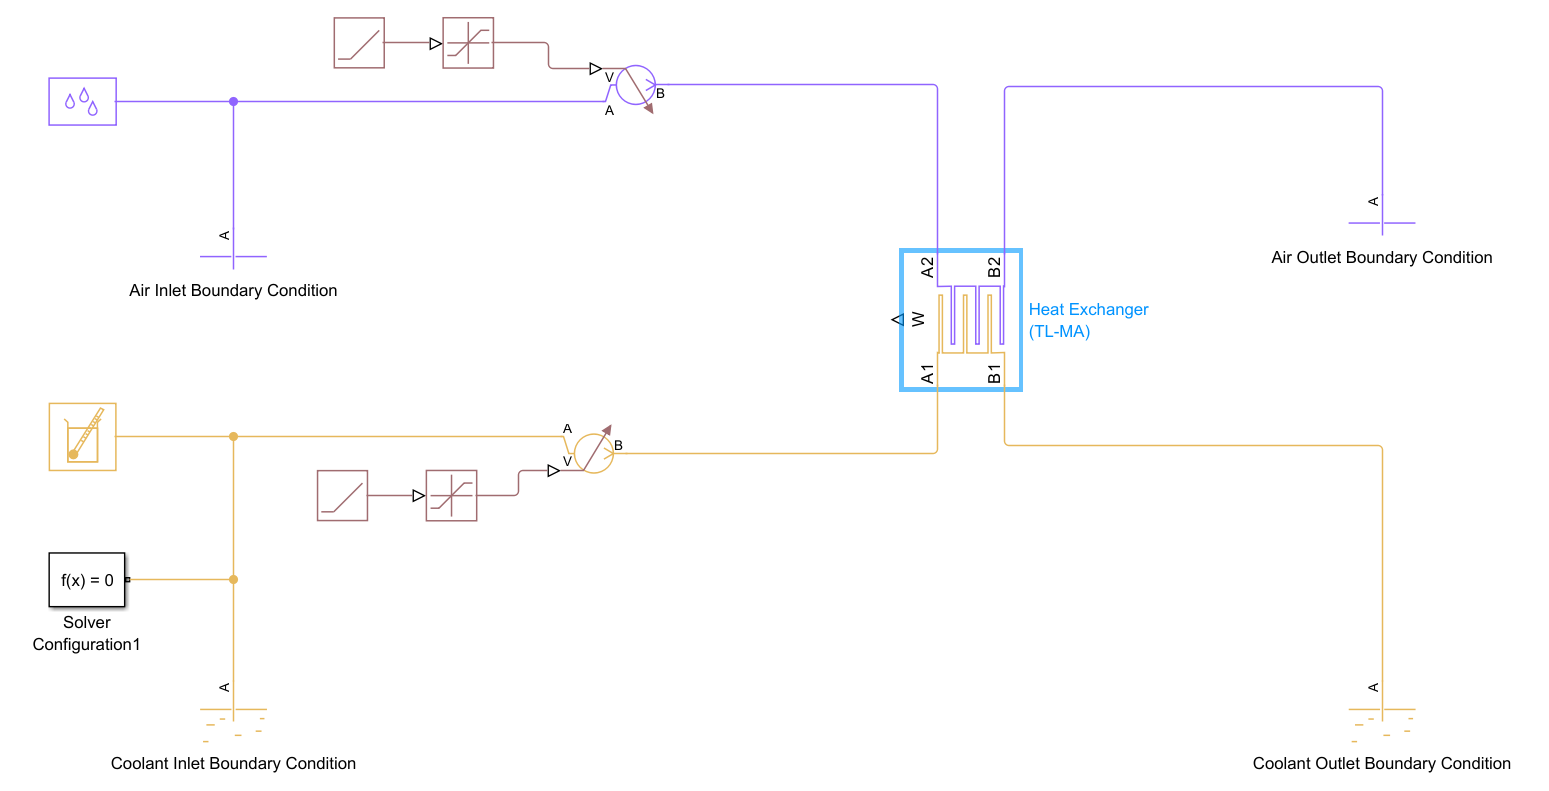

The model is setup with the above parameters. The Moist Air Side has the *Flow Geometry* set to Generic, 

On the Thermal Liquid side the model is initialized at the assumed loop pressure and the cold plate outlet temperature. On the air side the model is initialized at ambient pressure and temperature. As in previous models we set the cross-sectional areas of connected ports to similar values. On the Thermal Liquid side, this is the tube cross-sectional area. On the air side the flow area in the radiator. 

The parameter "Wall thermal mass" is also enabled, for danymic simulation this adds a capacitance to the component, making it more robust during fluctuations in dynamic simulations. 

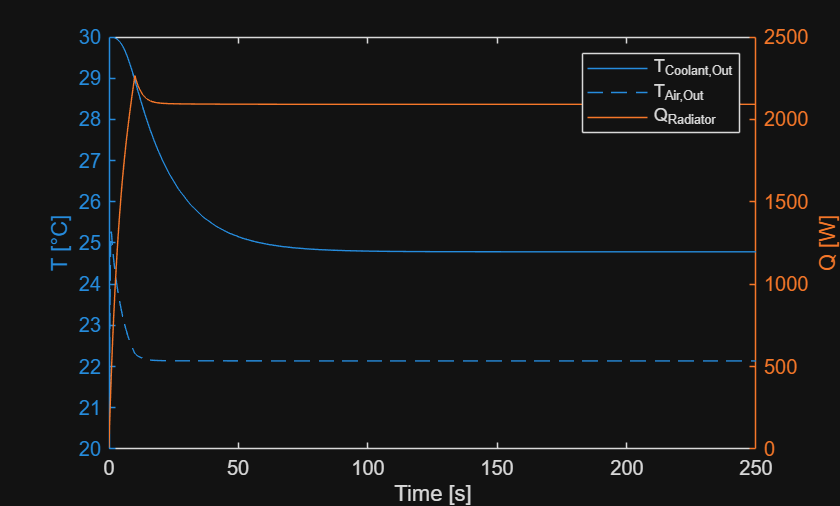

simInp = Simulink.SimulationInput("example_Radiator");
simInp = simInp.setModelParameter("StopTime","250");

simOut = sim(simInp);

TCoolantRadiatorOut = simOut.simlog.Heat_Exchanger_TL_MA.B1.T.series.values("degC");
TAirRadiatorOut     = simOut.simlog.Heat_Exchanger_TL_MA.B2.T.series.values("degC");
QRadiator           = simOut.simlog.Heat_Exchanger_TL_MA.Q2.series.values("W");
figure
yyaxis left
plot(simOut.tout,[TCoolantRadiatorOut,TAirRadiatorOut])
ylabel("T [°C]")
yyaxis right
plot(simOut.tout,QRadiator)
ylabel("Q [W]")
xlabel("Time [s]")
legend("T_{Coolant,Out}","T_{Air,Out}","Q_{Radiator}")

#### Determine the coolant side radiator pressure drop

Similar to the Pipe (TL) block the pressure drop for the Thermal Liquid side, when the Pressure loss model is set to Correlations for flow inside tubes is determined using a Haaland approximation to calculate the Darcy friction factor. 

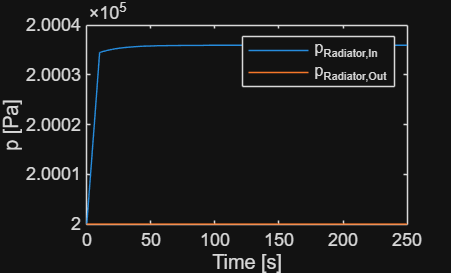

open_system("example_Radiator")

simInp = Simulink.SimulationInput("example_Radiator");
simInp = simInp.setModelParameter("StopTime","250");

simOut = sim(simInp);

pCoolantRadiatorIn  = simOut.simlog.Heat_Exchanger_TL_MA.A1.p.series.values("Pa");
pCoolantRadiatorOut = simOut.simlog.Heat_Exchanger_TL_MA.B1.p.series.values("Pa");

dpRadiator = pCoolantRadiatorIn-pCoolantRadiatorOut;


figure
plot(simOut.tout,[pCoolantRadiatorIn,pCoolantRadiatorOut])
ylabel("p [Pa]")
xlabel("Time [s]")
legend("p_{Radiator,In}","p_{Radiator,Out}")
hold off


disp(dpRadiator(end))

   35.9287



At steady state for the maximum flow rate, the current cold plate design produces a pressure drop of roughly 12 Pa which is as expected  small compared to what is caused by the cold plate and all additional piping. 

#### Fan parameterization

A fan will be used on the Moist Air side to create a forced air flow through the radiator. To model that component, we will use the Fan (MA) block. Again, as in the pump, we can use a vendor data sheet to parameterize the component. We will use the parameterization option 1D tabulated data - static pressure vs. flow rate at reference shaft speed. The pressure gain required at nominal conditions is:

[https://www.delta-fan.com/Download/HPAM-EC-fans/Spec/GTB036NUQ27R-M001.pdf](https://www.delta-fan.com/Download/HPAM-EC-fans/Spec/GTB036NUQ27R-M001.pdf)

[https://www.krugerfan.com/public/uploads/library-202220222022202203032929161603031313.pdf](https://www.krugerfan.com/public/uploads/library-202220222022202203032929161603031313.pdf)

pFanIn  = simOut.simlog.Intake.A.p.series.values("Pa");
pFanOut = simOut.simlog.Heat_Exchanger_TL_MA.B2.p.series.values("Pa");
dpFan = pFanIn-pFanOut;

disp(dpFan(end))

  851.9037



We will select a suitable  pump curve from a vendor